### Problem Statement

Water at 298K flows through a smooth, square duct with sides of 0.1m. The average water velocity is 8 m/s. The duct is 100m long. Calculate the power needed to pump the water. Compare your results with the power required to pump the same flow through a circular duct.

### Given Values

    s_sqr = 0.1;    %[m]
    D_cir = 0.1;    %[m]
    L = 100;        %[m]
    T = 298;        %[K]
    v_avg = 8;      %[m/s]

### Sketch

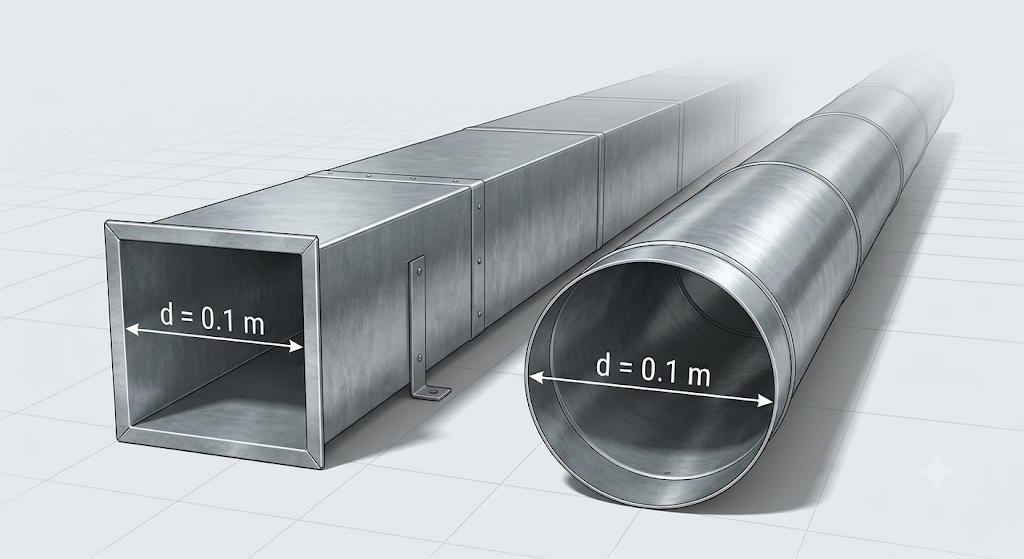

### Approach

- Solve hydrodiameter of the square duct.

- Perform table look up to solve for Reynold's number, Re

-         Assume atmospheric pressure (1atm = 101kpa)

-         Assume turbulent at Re>2000 internal flow

- Suspect turbulence from high velocity, so solve for Darcy friction factor, FD

- Use 1st law to solve for change in pressure

- Use first law to determine power required, w'

### Equations

            (1)        $D_h = \frac{4 A_c}{P_w}$

            (2)        $Re = \frac{\rho v_{\text{avg}} D_h}{\mu}$

            (3)        $\text{Constant} = P + \frac{\alpha}{2} \rho v^2 + \rho g z$

            (3.1)      $\Delta P_{L} = \sum h_L$

            (4)        $FD = \left(0.971 \ln Re - 1.64\right)^{-2}$

            (5)        $\dot{W} = \gamma Q h_L$

### Solution

    P_w = 4*s_sqr;%[m]                  find duct wetted perimeter
    A_c_sqr = s_sqr^2;%[m^2]            find square duct cross sectional area
    A_c_cir = pi()*0.25*D_cir^2;%[m^2]  find circle duct cross sectional area
    D_hydro = 4*A_c_sqr/P_w;%[m]            solve hydrodiameter of the square duct

    %Table look up
        state = waterState('T',T-272.15,'P',101.325);%embedded conversion in the function
        rho = (state.v_m3_kg)^-1;
        %mu = state.mu_kg_m_s;
        %Dynamic viscosity not included in function so found externally
        mu = 8.936e-4;%kg/m-s]

    Re = rho*v_avg*D_hydro/mu;%[1]      Reynold's number to determine turbulence
    FD = (0.79*log(Re)-1.64)^(-2);%[1]    Darcy friction factor
    h_l_maj = FD*rho*(v_avg^2)*(100/0.1)*0.5;%[Pa]
        %[m-kg-m2/m-m3-s2 = Pa]
        %has gamma incorporated in eq already

    P_delta = h_l_maj;  %via derivation of 1st law, eq 3.1
    
    w_dot_sqr = h_l_maj*v_avg*A_c_sqr;%[kw]
    w_dot_cir = h_l_maj*v_avg*A_c_cir;%[kw]

    power_dif = abs(w_dot_cir-w_dot_sqr);%[kw]

### Reflection

**Sanity check: **Values seem reasonable through out. I identified that the state function for table look ups does not actually include dynamic viscosity, mu, so this live script must be diligently reviewed for this hard coding instead of relying on the state function.

**Application: **The difference in power required for the square and circle duct shapes is significant. While rectangular ducts may be easier to manufacture and install (cheaper initially), there could be immense cost savings through using circular ducts over time.